Jordan Grotz

Configuration Space Assignment

2/6/23

Robot Arm and Movement Definiton 

clear
clc
%theta1 = 0:1:90;
%theta2 = 0:1:360;
%theta2 = zeros(91);
theta1 = 32;
theta2 = 57;
L1 = 3;
L2 = 3;




Create Polygon Obstacle

b_left_corner_x = 2;
b_left_corner_y = 2;
width = 1.2;
height = 6.5;
b_left_corner = [b_left_corner_x,b_left_corner_y];
p1 = b_left_corner;
p2 = b_left_corner+[width,0];
p3 = b_left_corner+[width,height];
p4 = b_left_corner+[0,height];
pgon = polyshape([p1(1),p2(1),p3(1),p4(1)],[p1(2),p2(2),p3(2),p4(2)]);

Workspace Definition

xlimit = [-(L1+L2),(L1+L2)];
ylimit = [-(L1+L2),(L1+L2)];

Plot Arm and Obstacle

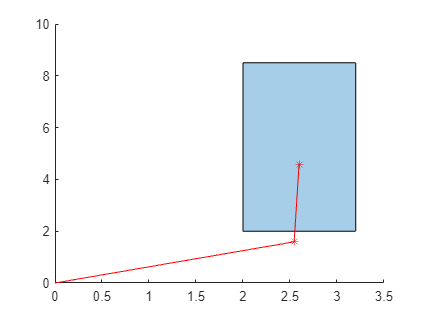

fig = figure;
xlim(xlimit)
ylim(ylimit)
plot(pgon)
[X2,Y2,Xf,Yf] = fkinematics(theta1,theta2,L1,L2);
if isinterior(pgon,X2,Y2) || isinterior(pgon,Xf,Yf)
    plot_bad_bot(X2,Y2,Xf,Yf);
else
    plot_good_bot(X2,Y2,Xf,Yf);
end

Configuration Space

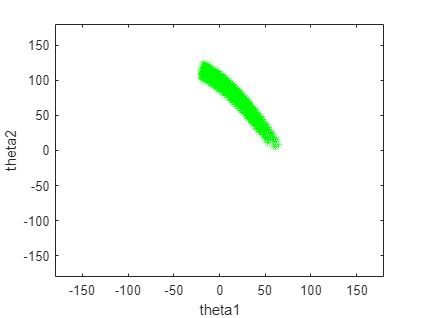

cspace = configuration_space(pgon,L1,L2);

Functions

function [x2,y2,xf,yf] = fkinematics(theta1,theta2,L1,L2)
    x2 = (cosd(theta1)*L1);
    y2 = (sind(theta1)*L1);
    xf = x2+(cosd(theta1+theta2)*L2);
    yf = y2+(sind(theta1+theta2)*L2);
end

function plot_good_bot(x2,y2,xf,yf)
    hold on
    %draw lines
    plot([0,x2,xf],[0,y2,yf],'-b');
    %draw dots
    plot(x2,y2, "Color", "Green", "Marker", "*")
    plot(xf,yf, "Color", "Green", "Marker", "*")
end

function plot_bad_bot(x2,y2,xf,yf)
    hold on
    %draw lines
    plot([0,x2,xf],[0,y2,yf],'-r');
    %draw dots
    plot(x2,y2, "Color", "Red", "Marker", "*")
    plot(xf,yf, "Color", "Red", "Marker", "*")
end

function [theta1s, theta2s] = inverse_kin(Xfs,Yfs,L1,L2)
    L3 = sqrt(Xfs.^2+Yfs.^2);
    theta2prime = acosd((L1.^2+L2.^2-L3.^2)./(2*L1*L2));
    theta2s = 180-theta2prime;
    alpha = atan2d(Yfs,Xfs);
    beta = acosd((L1.^2+L3.^2-L2.^2)./(2*L1*L3));
    theta1s = alpha-beta;
end

function [cspace] = configuration_space(obstacle,L1,L2)
    %max reach of the arm in x direction
    x_spaces = 0:0.1:(L1+L2);
    %max reach of the arm in y direction
    y_spaces = 0:0.1:(L1+L2);
    bad_spaces = zeros(length(x_spaces)*length(y_spaces),2);
    index = 0;
    for xs = x_spaces
        for ys = y_spaces
            if sqrt(xs^2+ys^2) <= L1+L2
                if isinterior(obstacle,xs,ys)
                    index = index + 1;
                    [bad_spaces(index,1),bad_spaces(index,2)] = inverse_kin(xs,ys,L1,L2);
                end
            end
        end
    end
    %clean up bad_spaces array
    %bad_spaces = bad_spaces(abs(bad_spaces) > 0);
    
    figure;
    plot(bad_spaces(1:index,1),bad_spaces(1:index,2),'*g');
    xlim([-180,180]);
    ylim([-180,180]);
    xlabel("theta1");
    ylabel("theta2");
    cspace = bad_spaces(1:index,:);
end